clc;
clear all;
close all;

run("Q310_Basic.mlx")

sys_dis_open =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 - 1.937 z^2 + 1.122 z - 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



c =          0    0.1604   -0.1958    0.0786


d =     1.0000   -1.9367    1.1220   -0.1421


sys_cont_close =
 
     7.8 s^3 + 205.7 s^2 + 601.4 s + 1276
  -------------------------------------------
  s^4 + 15.8 s^3 + 212.7 s^2 + 608.4 s + 1276
 
Continuous-time transfer function.


sys_dis_close =
 
  0.1328 z^3 - 0.3505 z^2 + 0.3048 z - 0.08705
  --------------------------------------------
  z^4 - 3.73 z^3 + 5.24 z^2 - 3.288 z + 0.778
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



c1 =          0    0.1328   -0.3505    0.3048   -0.0871


d1 =     1.0000   -3.7296    5.2395   -3.2878    0.7780


## generate data

tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s);

% t = 0:T_s_close:tfinal;
% u = gensig('sine' , tfinal/20 , tfinal ,T_s_close);

var_e=0.05;

e=sqrt(var_e);
Noise=(-e+(e+e)*rand(numel(t),1));
u=u+Noise;
y = lsim(sys_dis_open ,u ,t);



### smooth parameter variation 


for i=1:numel(t)
    paras(:,i)=[d(2:end),c]';
end



uu=round(numel(t)/3,0)

uu = 274

uuu=round(numel(t)*2/3,0)

uuu = 547

for temp=uu:uuu
    paras(:,temp)=[d(2:end)+d(2:end)*.05*(sin(.5*(temp-uu))),(c+c*.05*(sin(.5*(temp-uu))-1))]';
    y(temp)=[-(y(temp-1:-1:temp-3))',(u(temp:-1:temp-3))']*paras(:,temp);
end

for temp=uuu:numel(y)
    paras(:,temp)=[d(2:end)+d(2:end)*.08*(sin(.5*(temp-uu))),(c+c*.08*(sin(.5*(temp-uu))-1))]';
    y(temp)=[-(y(temp-1:-1:temp-3))',(u(temp:-1:temp-3))']*paras(:,temp);
end

sys_dis = tf(c+c*.0001*(sin(.05*(temp-uu))-1)' ,[1 -d(2:end)+d(2:end)*.0001*(sin(.05*(temp-uu)))'], T_s)

sys_dis =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 + 1.937 z^2 - 1.122 z + 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



ident_analog2 = d2c(sys_dis)

ident_analog2 =
 
  -0.7909 s^3 + 11.21 s^2 + 28.28 s + 132.9
  ------------------------------------------
  s^4 + 4.37 s^3 + 128.3 s^2 + 1839 s + 6022
 
Continuous-time transfer function.



legend('Input','Output') ;


[c2,d2]=tfdata(sys_dis,'v')

c2 =          0    0.1604   -0.1958    0.0786


d2 =     1.0000    1.9365   -1.1219    0.1421


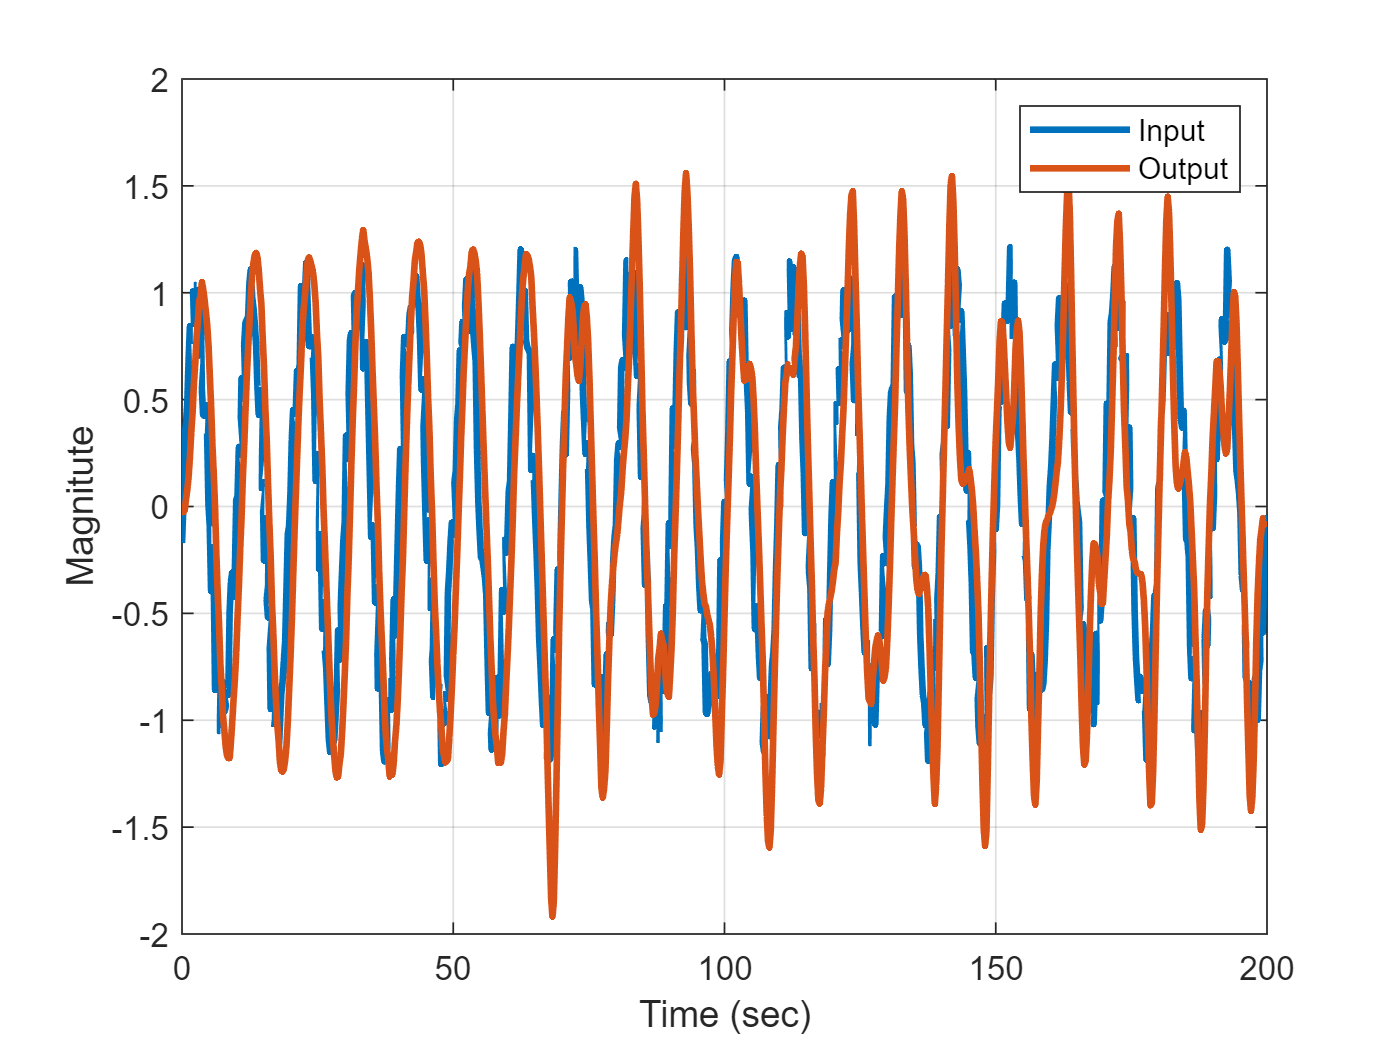


plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitute') ;
grid on
legend('Input','Output') ;

## Kalman Filter

N = numel(y) ;
% %--------------------------%
%choose number of parameters
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

% %--------------------------%
Nv=Parameters_in_num+Parameters_in_den;

p_KF(1:Nv,1:Nv,1:N)=zeros(Nv,Nv,N);
%intitial Conditions
theta_hat_KF(1:Nv,1:N)=zeros(Nv,N);
K_KF(1:Nv,1:N)=zeros(Nv,N);
var_e=0.05;

p_KF(1:Nv,1:Nv,1)=1e5*eye(Nv);p_KF(1:Nv,1:Nv,2)=p_KF(1:Nv,1:Nv,1);p_KF(1:Nv,1:Nv,3)=p_KF(1:Nv,1:Nv,2);


for i=(max(Parameters_in_num,Parameters_in_den)+1):N
    phi_KF(:,i)=[(y(i-1:-1:i-Parameters_in_den))',(u(i-1:-1:i-Parameters_in_num))']';
    K_KF(:,i) =p_KF(:,:,i-1)*phi_KF(:,i)*(1+phi_KF(:,i)'*p_KF(:,:,i-1)*phi_KF(:,i))^(-1) ;  
    p_KF(:,:,i)=p_KF(:,:,i-1)-p_KF(:,:,i-1)*phi_KF(:,i)*(1+phi_KF(:,i)'*p_KF(:,:,i-1)*phi_KF(:,i))^(-1)*phi_KF(:,i)'*p_KF(:,:,i-1)+var_e;
    theta_hat_KF(:,i)=theta_hat_KF(:,i-1)+K_KF(:,i)*(y(i)-phi_KF(:,i)'*theta_hat_KF(:,i-1));
end


Bode

ident_dis = tf(theta_hat_KF((Parameters_in_num+1):end,end)' ,[1 -theta_hat_KF(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
    0.1544 z^2 - 0.269 z + 0.1342
  ----------------------------------
  z^3 - 2.409 z^2 + 1.969 z - 0.5157
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
    0.7996 s^2 + 0.4593 s + 1.865
  ---------------------------------
  s^3 + 2.715 s^2 + 1.913 s + 4.235
 
Continuous-time transfer function.



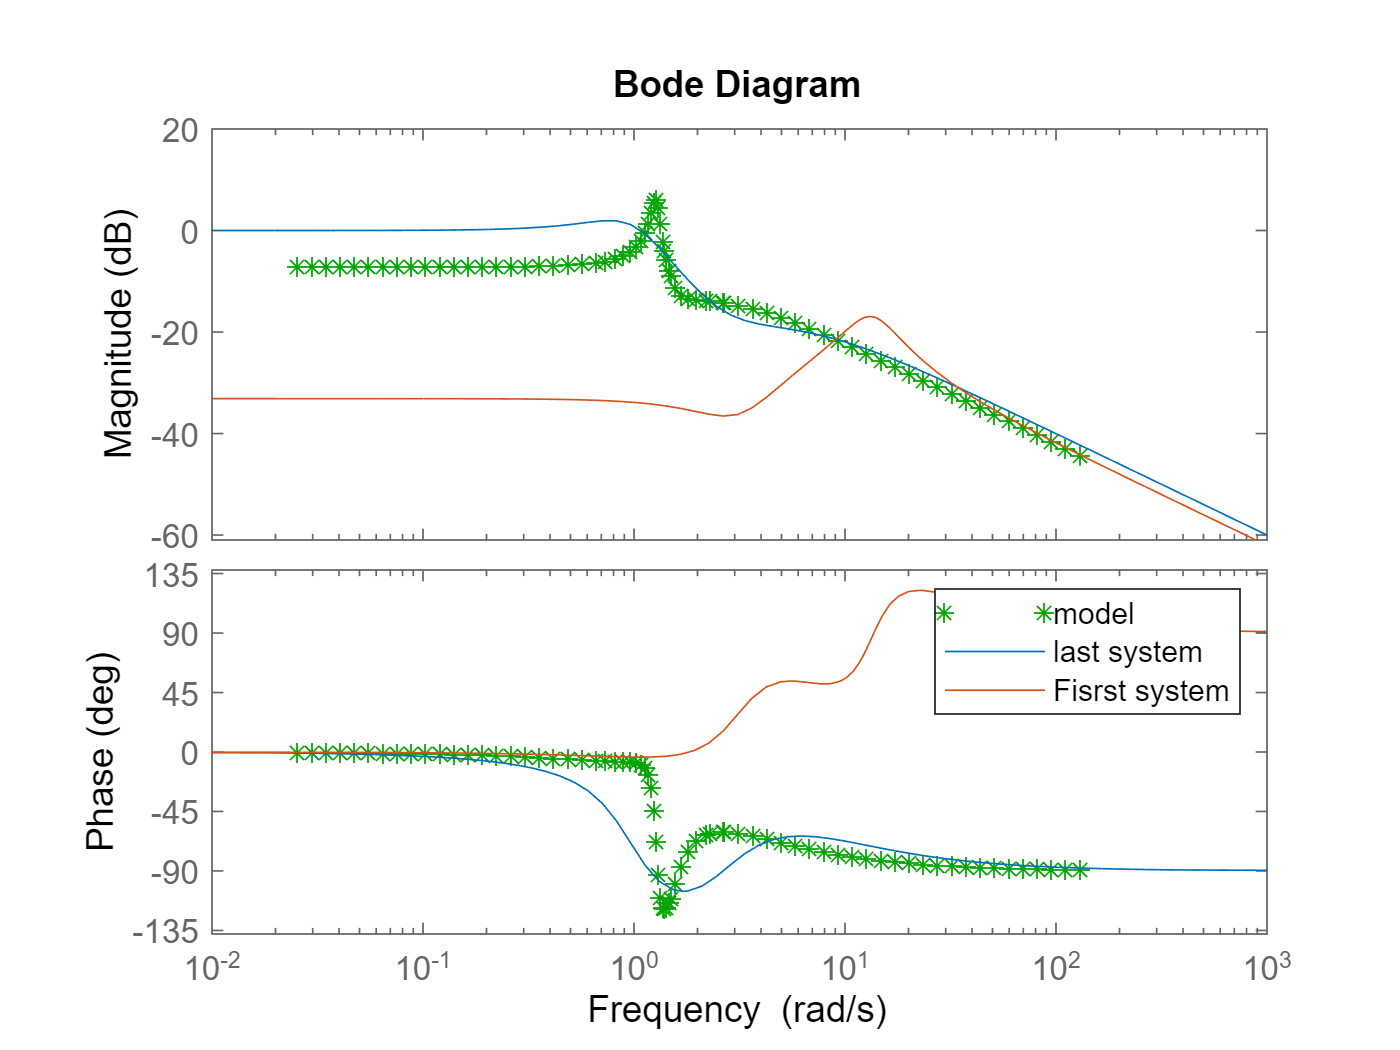

bode(ident_analog ,'g*',sys_cont_open ,ident_analog2)
legend('model ','last system','Fisrst system')

KF Convergence

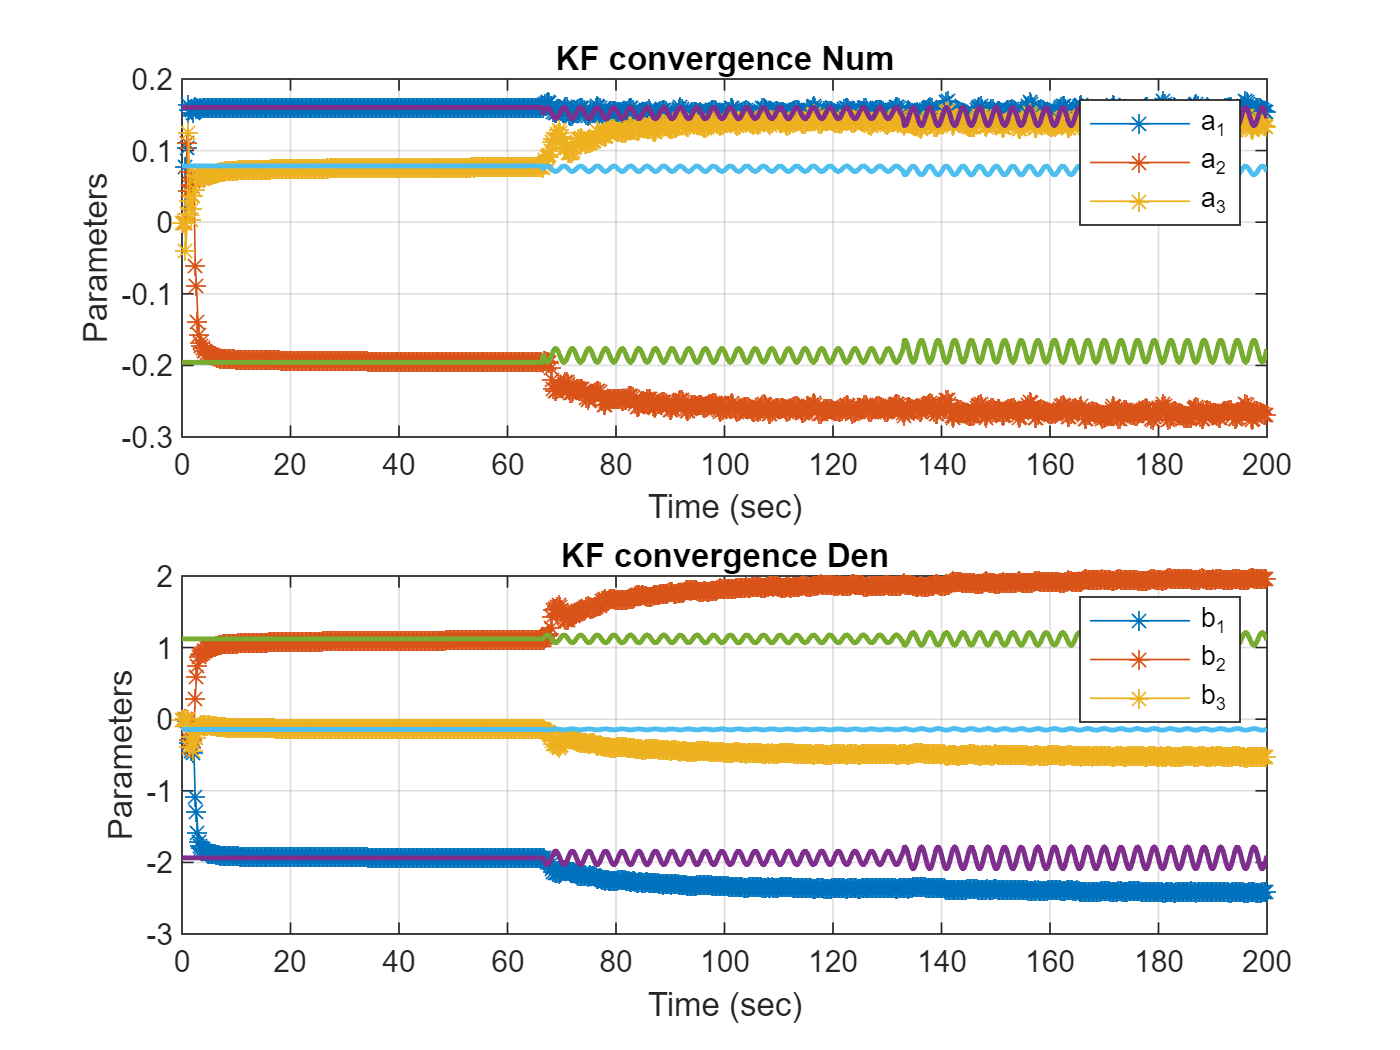


subplot(2,1,1)
plot(t , theta_hat_KF((Parameters_in_num+1):end,:) , '*-') ;
hold on
plot(t ,paras(5:end,:) , 'LineWidth' , 1.5)
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('KF convergence Num') ;
grid on
legend('a_1','a_2','a_3')
% xlim([0 6])
% ylim([-1 1])
hold off
%--------------------------------------------------------------
subplot(2,1,2)

plot(t , -theta_hat_KF(1:Parameters_in_num ,:) , '*-') ;
hold on
plot(t ,paras(1:Parameters_in_num ,:) , 'LineWidth' , 1.5)
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('KF convergence Den') ;
grid on
legend('b_1','b_2','b_3')
% xlim([0 6])
hold off

% ylim([-7  7])
